# Compare performance of pPSTH and population IT

load('N-30.mat');
load('Spikes.mat');

% choose a firing rate of 100 Hz, not bursty, make sure corr is 0.1-0.2
npop = 30;
nparams = size(c,1); % number of sets of firing rate parameters
ntrials = size(c,2)-5; % number of trials
params = c(:,ntrials+1:ntrials+5);
params = cell2mat(params);
lambda1 = params(:,1);
k1 = params(:,3);
fr_exact = params(:,5);
fr = round(fr_exact,-1); % round firing rate to nearest 10 Hz
burstiness = k1./lambda1;

Corr = zeros(nparams, ntrials);
for ii = 1:nparams
    for j = 1:ntrials
        Corr(ii,j)=c{ii,j}.corr;
    end
end
Corr = median(Corr,2);
Corr(Corr<0)=0;
corr_edges = 0:0.1:0.3;
corr_bin = discretize(Corr,corr_edges);
    
rows = find(fr==100 & burstiness >= 0.02 & burstiness <= 0.03 & corr_bin == 2);
row = rows(1);
Spikes1 = Spikes(row,:);

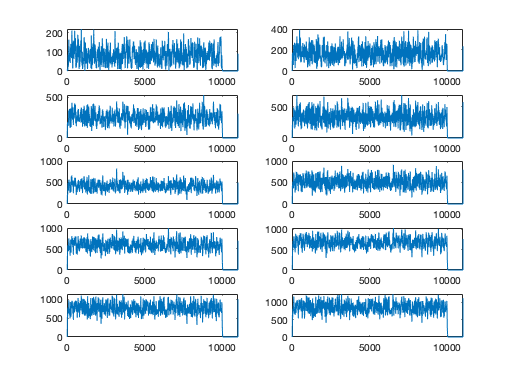

% for each trial, find the filter length that gives 1 error
close all hidden;
partition = 1:11001;
RT = zeros(1,ntrials);
T = [22 17 20 14 20 15 20 21 18 18];
time_vec = [];
for i = 1:ntrials
    for j = 1:npop
        time_vec = [time_vec; find(Spikes1{1,i}(:,j))];
    end
    time_vec = [time_vec; 11000.*ones(npop,1); 11001.*ones(npop,1)];
    
    r = zeros(1, length(partition));
    for k = 1:length(partition)
        r(k) = 1000.*length(find(time_vec == partition(k)))/npop; % firing rate in bin i, converted to spikes/s
    end
    t = T(1,i);
    h = 1/t.*ones(1,t);
    PSTH = filter(h,1,r);
    subplot(5,2,i)
    plot(PSTH)
    rt = pPSTHPerformance(PSTH);
    RT(1,i) = rt;
end

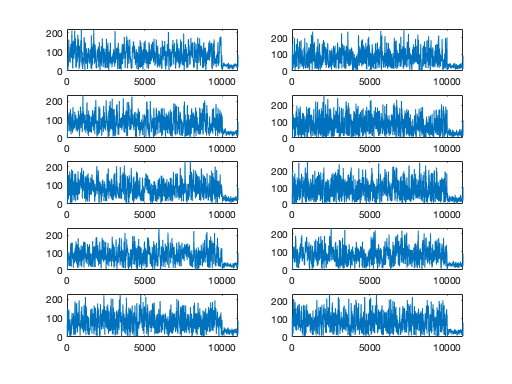

m = 10;
rng(5899);
alpha1 = 0.8;
alpha2 = 0;
lambda1 = c{row,11};
lambda2 = c{row,12};
k1 = c{row,13};
k2 = c{row,14};
partition = 1:11001;
newspikes_all = RenewalProcess(m, alpha1, alpha2, lambda1, lambda2, k1, k2);
newspikes_all = reshape(newspikes_all,1000,m,10);
newspikes = cell(1,ntrials);
for i = 1:ntrials
    newspikes_i = newspikes_all(:,:,i);
    newspikes_i = reshape(newspikes_i,1000,m);
    newspikes{i} = newspikes_i;
end

for i = 1:ntrials
    time_vec = [];
    for j = 1:npop
        time_vec = [time_vec; find(Spikes1{1,i}(:,j))];
    end
    new_time_vec = [];
    for j = 1:m
        new_times = find(newspikes{1,i}(:,j))+10000;
        new_time_vec = [new_time_vec; new_times];
    end
    
    time_vec = [time_vec; new_time_vec; 11000.*ones(npop-m,1); 11001.*ones(npop-m,1)];
    
    r = zeros(1, length(partition));
    for k = 1:length(partition)
        r(k) = 1000.*length(find(time_vec == partition(k)))/npop; % firing rate in bin k, converted to spikes/s
    end    
    t = T(1,i);
    h = 1/t.*ones(1,t);
    PSTH = filter(h,1,r);
    subplot(5,2,i)
    plot(PSTH)
end

% see how sensitive PSTH is to all cells responding
M = 0:29;
rng(5899);
alpha1 = 0.8;
alpha2 = 0;
lambda1 = c{row,11};
lambda2 = c{row,12};
k1 = c{row,13};
k2 = c{row,14};
partition = 1:11001;
RT_PSTH = zeros(length(M),ntrials);
newspikes = cell(length(M),ntrials);
    
for l = 1:length(M)
    m = M(l);
    % simulate m cells not responding to the stimulus
    newspikes_all = RenewalProcess(m, alpha1, alpha2, lambda1, lambda2, k1, k2);
    newspikes_all = reshape(newspikes_all,1000,m,10);
    for k = 1:ntrials
        newspikes_k = newspikes_all(:,:,k);
        newspikes_k = reshape(newspikes_k,1000,m);
        newspikes{l,k} = newspikes_k;
    end
    
    % get reaction time from PSTH for each trial
    for k = 1:ntrials
        time_vec = [];
        for j = 1:npop
            time_vec = [time_vec; find(Spikes1{1,k}(:,j))];
        end
        new_time_vec = [];
        for j = 1:m
            new_times = find(newspikes{l,k}(:,j))+10000;
            new_time_vec = [new_time_vec; new_times];
        end
    
        time_vec = [time_vec; new_time_vec; 11000.*ones(npop-m,1); 11001.*ones(npop-m,1)];
    
        r = zeros(1, length(partition));
        for i = 1:length(partition)
            r(i) = 1000.*length(find(time_vec == partition(i)))/npop; % firing rate in bin k, converted to spikes/s
        end    
        t = T(1,k);
        h = 1/t.*ones(1,t);
        PSTH = filter(h,1,r);
        rt = pPSTHPerformance(PSTH);
        RT_PSTH(l,k) = rt;
    end
end

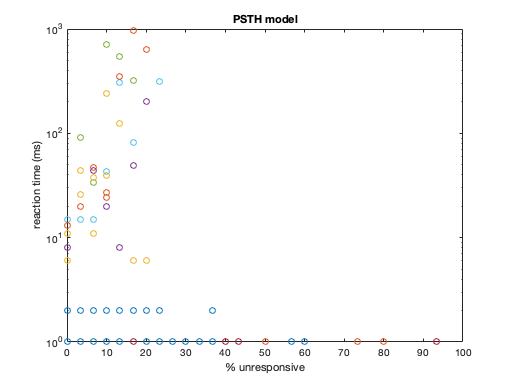

close all hidden;
percent = 100.*M./30;
for k = 1:ntrials
    semilogy(percent,RT_PSTH(:,k),'o')
    hold on
end
hold off
xlabel('% unresponsive')
ylabel('reaction time (ms)')
title('PSTH model')

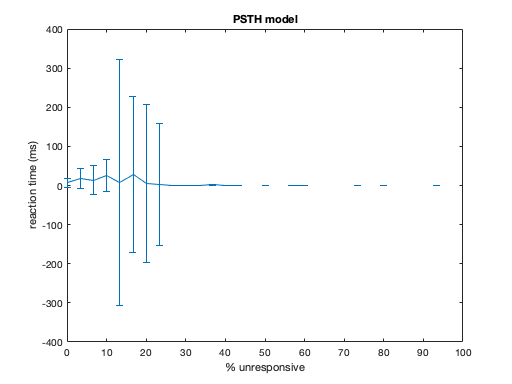


RT_PSTH_avg = median(RT_PSTH,2,'omitnan');
RT_PSTH_error = iqr(RT_PSTH,2);
errorbar(percent,RT_PSTH_avg,RT_PSTH_error)
xlabel('% unresponsive')
ylabel('reaction time (ms)')
title('PSTH model')

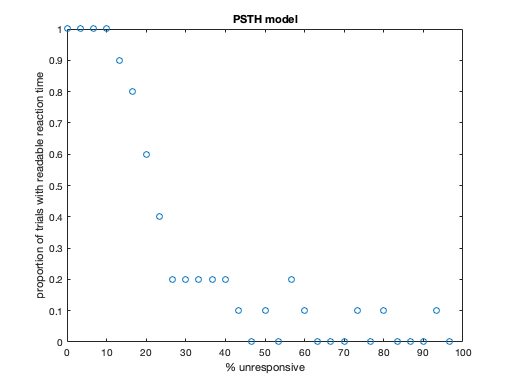


fraction = zeros(1,length(M));
for l = 1:length(M)
    fraction(l) = sum(~isnan(RT_PSTH(l,:)))/ntrials;
end
plot(percent,fraction,'o')
xlabel('% unresponsive')
ylabel('proportion of trials with readable reaction time')
ylim([0 1])
title('PSTH model')

close all hidden;
% see how sensitive IT is to all cells responding
RT_IT = zeros(length(M),ntrials);

for l = 1:length(M)
    m = M(l);
    
    for k = 1:ntrials
        C = cell(1,npop);
        for i = 1:npop
            spikes = Spikes1{k};
            spikeind = find(spikes(:,i));
            isi = diff(spikeind);
            [d, ~] = SumGamFit(isi, lambda1, lambda2, k1, k2);
            C{i} = d;
        end
        
        dt2 = 0.001;
        stim = zeros(1/dt2,npop);
        stim(:,1:npop-m) = zeros(1/dt2,npop-m);
        stim(:,npop-m+1:npop) = newspikes{l,k};
        spikes = [spikes; stim; ones(1,npop)];    
        
        IT = zeros(11001,npop);
        for i = 1:npop
            spikeind = find(spikes(:,i));
            isi = diff(spikeind);
            isi = [spikeind(1); isi];
            IT(:,i) = InfoTrain(C{i}, isi);
        end
        IT = sum(IT, 2);
        optimal_threshold = c{198,k}.performance(1,1);
        [~, rt] = Performance(IT, optimal_threshold);[~, rt] = Performance(IT, optimal_threshold);
        RT_IT(l,k) = rt;
    end
    
end

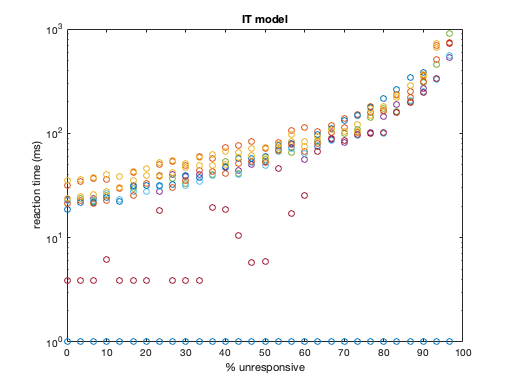

close all hidden;
for k = 1:ntrials
    semilogy(percent,RT_IT(:,k),'o')
    hold on
end
hold off
xlabel('% unresponsive')
ylabel('reaction time (ms)')
title('IT model')

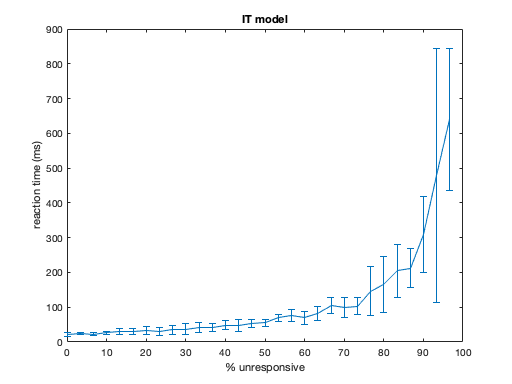


RT_IT_avg = median(RT_IT,2,'omitnan');
RT_IT_error = iqr(RT_IT,2);
errorbar(percent,RT_IT_avg,RT_IT_error)
xlabel('% unresponsive')
ylabel('reaction time (ms)')
title('IT model')

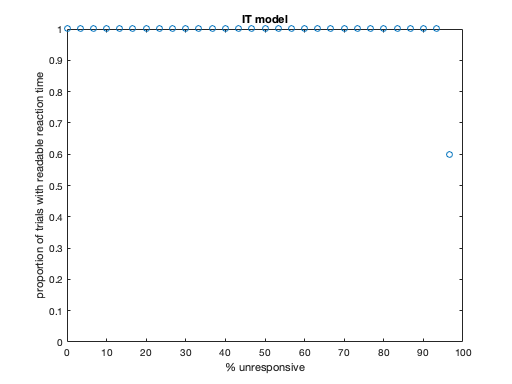


fraction = zeros(1,length(M));
for l = 1:length(M)
    fraction(l) = sum(~isnan(RT_IT(l,:)))/ntrials;
end
plot(percent,fraction,'o')
xlabel('% unresponsive')
ylabel('proportion of trials with readable reaction time')
ylim([0 1])
title('IT model')